# Task 

The coursework will use a subset of MNIST handwritten digit dataset (will be provided) that you have prepared in the lab sessions (see lab materials in Appendix), and you will perform the  following tasks: 

Compulsory Section (You must complete this part) Design and implement a single layer perceptron to distinguish the digit 6 from the other 9 digits,  

i.e., when the input is 6, the output will be +1, and -1 otherwise.

 Do your experiment follow these  guidelines: 

• Split the data into a training set and a testing set. 

• Plot at least 4 graphs (e.g., 2 different sets of initial weight, 2 different training rates) of  error over time (%-incorrect classification on y axis, training epochs on x axis) for the  training set. 

• Plot the corresponding graphs for the testing set. 

Explain the stopping criteria you used to terminate training.  

# Load and display the MNIST dataset

Tips: 

1. In loading the MNIST data, probably you will rely on the following functions in Matlab:  fopen, fread and fclose.

2. In displaying the data, you will need to use the following functions: reshape, imagesc  and imshow. 

3. Just type ‘help XXX‘ in matlab to see how to use the above functions. 

4. If you encounter the ‘out of memory’ problem in Matlab, which means the data is too large to fit in to the memory, and you have to delete unnecessary variables in the  workspace or save them to the hard disk

load("MNIST_subset.mat")

# Data preprocessing:

1. Firstly, please repeat lab1 to load the MNIST dataset to Matlab. As the original  MNIST dataset contains 60000 digits for training, which is too large for our lab  sessions. Therefore, we only use a subset of the first 1000 digits for training. Based  on the lab1 sample code, you can achieve this by using the following code: 

%tr_label= tr_label(1:1000,1);
%tr_feats= tr_feats(1:1000,:);

2. To get a general picture of the data that we are going to process, you can count how  many samples are contained in the training set for each digit. You can use the  following code: 

% for i=0:9 
%     num_of_sample(i+1)=size(find(tr_label==i),1);  
% end
% num_of_sample

you could see that the number of  samples for each digit is roughly the same. You can also try to display all the samples  for each digit contained in the training set

It is sometimes necessary to normalize the data to make them more comparable. The  aim of normalization is to make the Euclidean normof each digit equal to 1. 

You can judge by yourself in the future lab sessions that  whether this normalization step is necessary or not.  

norms = sqrt(sum(tr_feats.^2, 2)); % 计算每一行的范数并存储在 norms 中
% 标准化矩阵的每一行
tr_feats = tr_feats.*100 ./ norms; % 将矩阵每一行除以对应的范数

1. Treat digit ‘2’ as positive, digit ‘5’ as negative, learn a percetron. 

Try to visualize  the samples that are most likely to be ‘2’ or most likely to be‘5’. 

Also try to visualize  the wrongly classified samples.  

num_of_sample =     97   116    99    93   105    92    94   117    87   100


2. Now consider four digits, ‘2’, ‘5’ ‘1’, and ‘7’. If we consider ‘2’ and ‘5’ are more  visually alike, and the same for ‘1’ and ‘7’, then we could design a ‘parent’  perceptron that consider ‘2’ and ‘5’ to be positive, ‘1’ and ‘7’ to be negative. We can  also design two ‘child’ perceptrons, one for classifying ‘2’ against ‘5’, and the other  distinguishes ‘1’ from ‘7’. Therefore, in total we need three perceptrons to classify  these four digits. Do you have some other ideas? Try to implement them and compare  the results. 

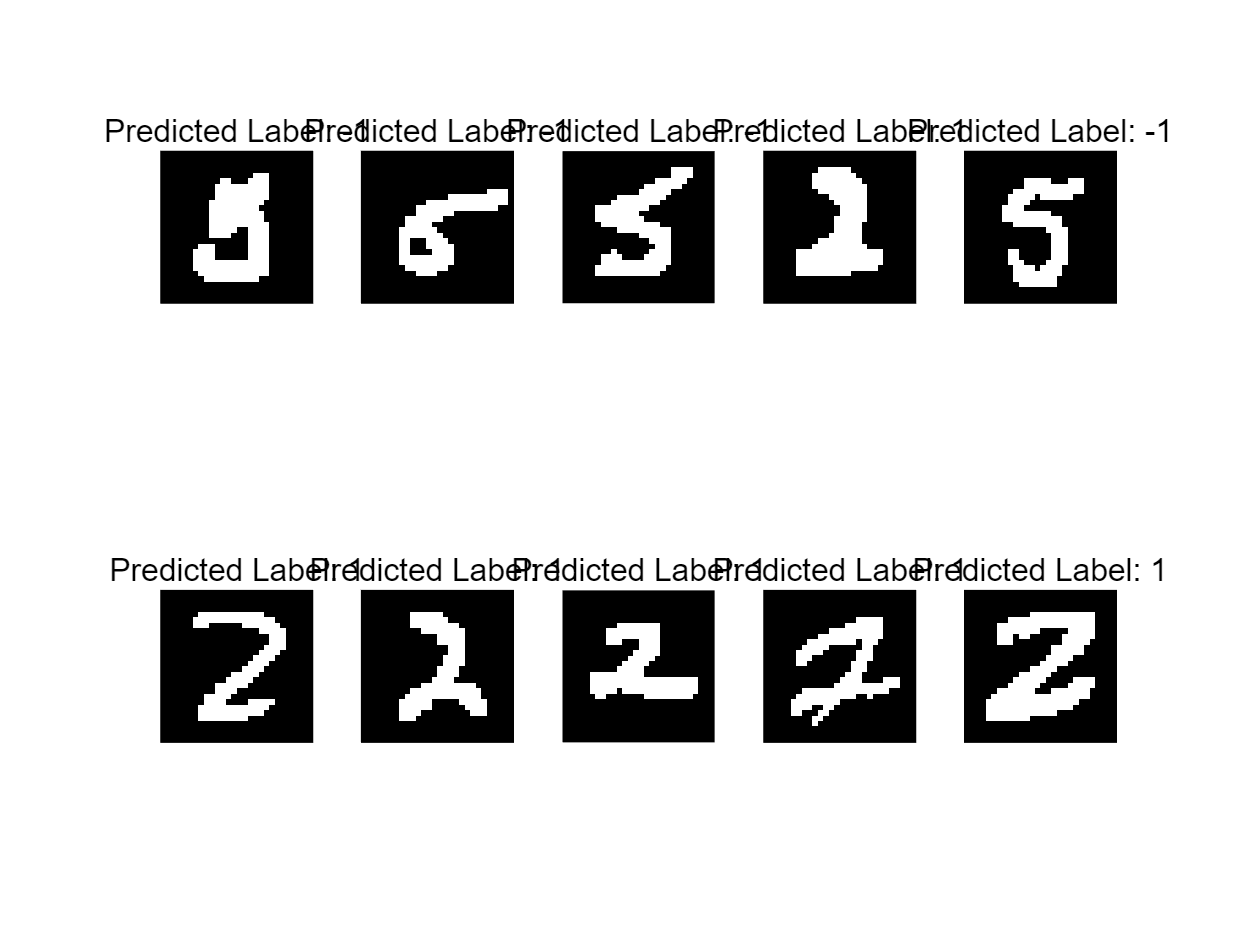

% 从测试数据中随机选择10张图片
num_images = 10;
selected_indices = randperm(size(merged_data, 1), num_images);
selected_images = merged_data(selected_indices, :);
% 预测每张图片的标签
predicted_labels = sign(selected_images * w + b);
% 将每张图片的特征转换为 28x28 的矩阵
reshaped_images = reshape(selected_images', [28, 28, 1, num_images]);
% 呈现图片及其预测的标签
figure;

for i = 1:num_images
    subplot(2, 5, i);
    imshow(reshape(selected_images(i, :), [28, 28])');
    title(['Predicted Label: ', num2str(predicted_labels(i))]);
end

Now consider all the 10 digits. Please think by yourself that how many  perceptrons do you need to recognize them. Then implement it!